# Tube Poincare sections in the Earth realm

# L1 Lyapunov orbits based on differential corrector for fixed C

## Set parameters

global FORWARD tol mu a Lpt
FORWARD = 1;
tol = 1e-10;
a=1;
Lpt = 1;
mu = 0.01215; % Earth-Moon, approximately

mu1 = 1-mu ; % shorthand for mass m1 in non-dimensional units
mu2 = mu   ; % shorthand for mass m2 in non-dimensional units

% x-value of Lagrange point Lpt
xLpt = Lptpos(mu, Lpt) ;
CLpt = -2*energy([xLpt 0 0 0],mu); % Jacobi constant of  Lagrange point Lpt

T = 2*pi ; % period of primaries in non-dimensional units

% Create Ubar grid for making zero velocity curves (just once)
include_constant = 0 ;

% Define grid for (X,Y) space
x_range = linspace(-1.5, 1.5, 1000);  % Adjust limits and resolution as needed
y_range = linspace(-1.5, 1.5, 1000);
[xx, yy] = meshgrid(x_range, y_range);

% Compute Ubar on the grid
Ubar = - mu1 ./ sqrt((xx + mu2).^2 + yy.^2) ...
       - mu2 ./ sqrt((xx - mu1).^2 + yy.^2) ...
       - 0.5 * (xx.^2 + yy.^2) - 0.5 * mu1 * mu2 * include_constant;

## Eigenvalues for linearized dynamics

mubar=mu/abs(xLpt-1+mu)^3 + (1-mu)/abs(xLpt+mu)^3;

aa=1+2*mubar;
b =mubar -1 ;

% The eigenvalues analytically

% stable/unstable eigenvalue is +/- lam, exponential rate
% center motion eigenvalue is a frequency nu
lam = sqrt( 0.5*(mubar-2 +sqrt(9*mubar^2-8*mubar)) ); 
nu  = sqrt(-0.5*(mubar-2 -sqrt(9*mubar^2-8*mubar)) );


## Compute small periodic orbit (planar Lyapunov orbit)

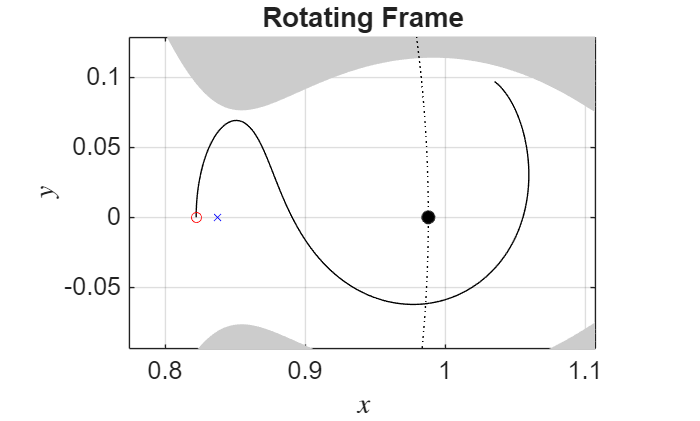

% pick based on Jacobi constant, C
C  = 3.165 ;

% pick initial x value slightly to the left of Lpt
x0 = xLpt - 0.015 ; 

% Initial state along x-axis with only y-velocity, 
% calculated from Jacobi constant
X0 = [ x0 0 0 ydot_from_x(x0,C)] ;

% estimated period for small orbit
Tpo = 2*pi/nu ; 

% slightly larger than one half period
tfinal = Tpo/2 + 0.9;

tol = 1e-8;
opts = odeset('AbsTol',tol,'RelTol',3*tol);
[t,X] = ode45(@(t,X) prtbp(t,X), [0 tfinal], X0, opts) ;

figure
h1=plot(X(:,1),X(:,2),'k','DisplayName','Trajectory');
hold on
h2=plot(X(1,1),X(1,2),'ro','DisplayName','Initial Point');
h3=plot(xLpt,0,'bx','DisplayName','Lagrange Point');

% plot zero velocity curve
% Define level set value
level_value = -C/2; % Adjust based on the desired level set

if level_value < max(Ubar(:)) % can only plot forbidden realm if E < E_L4
    % Plot filled contour in gray
    contourf(xx, yy, Ubar, [level_value, max(Ubar(:))], 'LineColor', 'none');
    colormap(0.8*[1 1 1]); % Set colormap to gray
    clim([level_value, max(Ubar(:))]); % Fix color scale
end 

earthmun % plot Earth, Moon and Moon's orbit to scale, remove if not Earth-Moon system

% Automatically adjust axis limits based on X data
x_min = min(X(:,1)); x_max = max(X(:,1));
y_min = min(X(:,2)); y_max = max(X(:,2));

% Add some padding for better visualization
padding_factor = 0.2; % 20% padding
x_pad = (x_max - x_min) * padding_factor;
y_pad = (y_max - y_min) * padding_factor;

title('Rotating Frame'); 
xlabel('$x$', 'Interpreter', 'latex'); 
ylabel('$y$', 'Interpreter', 'latex'); 
set(gca,'fontsize',15)
axis equal; grid on

xlim([x_min - x_pad, x_max + x_pad]);
ylim([y_min - y_pad, y_max + y_pad]);

## Differential Correction of initial guess if it crosses x-axis

x0g = X0; % initial guess

tol = 1e-13; % tolerance to use for numerical integration
[x0po,t1] = liadifcor_C(x0g,C);

Attempt: 1 vx1: 1.167e-01
Attempt: 2 vx1: -2.732e-02
Attempt: 3 vx1: -1.544e-03
Attempt: 4 vx1: -4.893e-06
Attempt: 5 vx1: -4.913e-11
Attempt: 6 vx1: -7.158e-15


## Integrate and plot Lyapunov orbit

Tpo = 2*t1 ;

tspan = 0:0.001*Tpo:Tpo;

C = -2*energy(x0po,mu) ;

x0po(1)

ans = 0.8200


opts = odeset('AbsTol',tol,'RelTol',250*tol);
[t,X] = ode45(@(t,X) prtbp(t,X), tspan, x0po, opts) ;

% check how 'closed' the closed orbit is
X(end,:)' - x0po(:)

ans = 1.0e-10 *

    0.2077
   -0.0618
    0.5558
   -0.2340


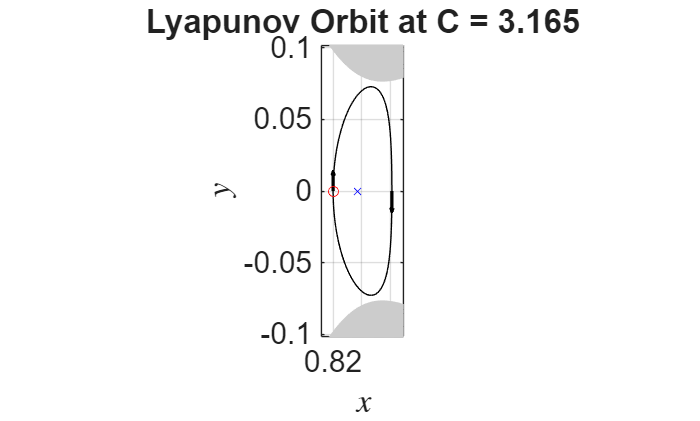


% Plot differentially corrected orbit

figure
plot(X(:,1),X(:,2),'k');

% add arrows to show the motion
hold on
arrowscal = 0.5; N = length(X); i = floor(1:N/2:N);
quiver(X(i,1), X(i,2), X(i,3), X(i,4), arrowscal,'k','linewidth',2)

h2=plot(X(1,1),X(1,2),'ro','DisplayName','Initial Point');
h3=plot(xLpt,0,'bx','DisplayName','Lagrange Point');

% plot zero velocity curve
% Define level set value
level_value = -C/2; % Adjust based on the desired level set

if level_value < max(Ubar(:)) % can only plot forbidden realm if E < E_L4
    % Plot filled contour in gray
    contourf(xx, yy, Ubar, [level_value, max(Ubar(:))], 'LineColor', 'none');
    colormap(0.8*[1 1 1]); % Set colormap to gray
    clim([level_value, max(Ubar(:))]); % Fix color scale
end 

earthmun % plot Earth, Moon and Moon's orbit to scale, remove if not Earth-Moon system

% Automatically adjust axis limits based on X data
x_min = min(X(:,1)); x_max = max(X(:,1));
y_min = min(X(:,2)); y_max = max(X(:,2));

% Add some padding for better visualization
padding_factor = 0.2; % 20% padding
x_pad = (x_max - x_min) * padding_factor;
y_pad = (y_max - y_min) * padding_factor;

title('Rotating Frame'); 
xlabel('$x$', 'Interpreter', 'latex'); 
ylabel('$y$', 'Interpreter', 'latex'); 
set(gca,'fontsize',15)
axis equal; grid on

xlim([x_min - x_pad, x_max + x_pad]);
ylim([y_min - y_pad, y_max + y_pad]);

title(['Lyapunov Orbit at C = ', num2str(C,'%0.12g')], 'FontSize', 18);
xlabel('$x$', 'Interpreter', 'latex'); 
ylabel('$y$', 'Interpreter', 'latex'); 

set(gca,'Fontsize',18)

## Compute Monodromy Matrix

[~,~,M,PHI]=PHIget(x0po,Tpo);

% M is the monodromy matrix
det(M) % should be 1

ans = 1.0000


eigenvalues = eig(M);

sorted_eigs = sort(abs(eigenvalues), 'descend'); % Sort by magnitude

format short e
fprintf('Eigenvalues of M (sorted by magnitude):\n');

Eigenvalues of M (sorted by magnitude):


disp(sorted_eigs);

   2.1663e+03
   1.0000e+00
   1.0000e+00
   4.6162e-04




lam1 = sorted_eigs(1);
lam2 = sorted_eigs(4);

lam1 - 1/lam2 % should be close to zero

ans =    3.5134e-06


## Integrate and plot manifold and chosen Poincare section cut

global t_wait primary_section direction_global x_poincare
% used by x_axis_crossing event function

x0=x0po ;

stbl=-1; % (+1) stable or (-1) unstable manifold
dir =+1; 

if stbl == -1
    manifold_title = 'Unstable';
    manifold_color = 'r';
else
    manifold_title = 'Stable';
    manifold_color = 'b';
end

% Variable initialization
xsos =[]; ysos =[];
xdsos=[]; ydsos=[];
tsos = []; frac_sos = []; x_init = [];

FORWARD = 1 ;
tol = 1e-12;
RELTOL = max([2.25e-14,30*tol]) ;

% Adjust the next two times to ensure which cut you get

% PICK A LONG ENOUGH TIME
tf =    5 ; % max time to integrate manifold trajectories looking for event
tf = -stbl*tf;

% THIS MAY VARY, DEPENDING ON C
t_wait = 1 ; % duration (abs(time)) to wait before stopping at event 

Poincare_XY_const = 2 ; % 1 for crossing parallel to x-axis  
                        % 2 for crossing parallel to y-axis (x = x_poincare)  
                        % 3 for apse

primary_section =  1 ; % Section U {y=0, x < 1-mu}
direction_global=  1 ; % 0 means doesn't matter; sign(v-yel) = direction_global = +/-1

if Poincare_XY_const == 1
    options = odeset('AbsTol',tol,'RelTol',RELTOL,...
        'Events',@x_axis_crossing);
    % x_axis_crossing uses global variables
    % global t_wait primary_section direction_global
elseif Poincare_XY_const == 2
    options = odeset('AbsTol',tol,'RelTol',RELTOL,...
        'Events',@y_axis_crossing);
    % y_axis_crossing uses global variables
    % global t_wait primary_section direction_global x_poincare
    x_poincare = 1-mu ;
elseif Poincare_XY_const == 3
    options = odeset('AbsTol',tol,'RelTol',RELTOL,...
        'Events',@poincare_event_func_peri_appo);
end

% frac =  number between 0 and 1 to parameterize manifold
Number_points_along_manifold_cut = 100 ;
frac = linspace(0,1,Number_points_along_manifold_cut) ;

% These are the initial conditions along the chosen Lyapunov orbit manifold
x_init = orbitman2D(x0,Tpo,frac,stbl,dir); % global FORWARD tol mu

% This steps through each initial condition and plots
% the manifold up to the chosen Poincare section

tic
figure

for k_init = 1:size(x_init,1)
    
    x0W_frac = x_init(k_init,:) ;
    [tW,xW,te,xe,ie] = ode113(@prtbp,[0 tf],x0W_frac,options);

    plot(xW(:,1),xW(:,2),manifold_color);
    
    if k_init == 1
        hold on
    end

    kk=1;

    xsos (k_init) = xe(kk,1); % x
    ysos (k_init) = xe(kk,2); % y
    xdsos(k_init) = xe(kk,3); % xdot
    ydsos(k_init) = xe(kk,4); % ydot

    tsos     (k_init) = te(kk)  ; % time of cut
    frac_sos (k_init) = frac(k_init)  ; % trakectory label as fraction \in [0,1]

end
toc

Elapsed time is 1.272823 seconds.


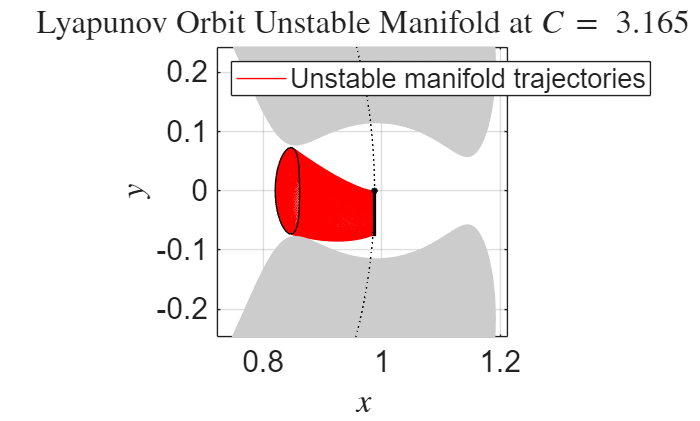


plot(x_poincare,ysos,'k.-'); % plot location of intersection
plot(X(:,1),X(:,2),'k'); % plot initial periodic orbit

% plot zero velocity curve
% Define level set value
level_value = -C/2; % Adjust based on the desired level set

if level_value < max(Ubar(:)) % can only plot forbidden realm if E < E_L4
    % Plot filled contour in gray
    contourf(xx, yy, Ubar, [level_value, max(Ubar(:))], 'LineColor', 'none');
    colormap(0.8*[1 1 1]); % Set colormap to gray
    clim([level_value, max(Ubar(:))]); % Fix color scale
end 

earthmun % plot Earth, Moon and Moon's orbit to scale, remove if not Earth-Moon system

grid on
axis equal
axis square
axis equal
xlim([0.675 1.268])
ylim([-0.314 0.279])
title(['Lyapunov Orbit ', manifold_title, ' Manifold at $C =$ ', num2str(C,'%0.12g')], ...
    'FontSize', 18,'Interpreter','latex');
legend([manifold_title ' manifold trajectories'],'location','northwest')
xlabel('$x$', 'Interpreter', 'latex'); 
ylabel('$y$', 'Interpreter', 'latex'); 
set(gca,'fontsize',18)

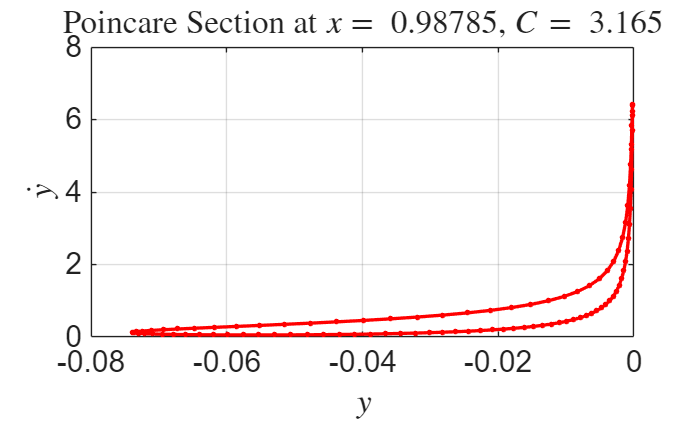


figure
% Poincare section
if Poincare_XY_const == 1
    plot(xsos,xdsos,manifold_color,'linewidth',2);
    grid on;
    axis square
    xlabel('$x$', 'Interpreter', 'latex'); 
    ylabel('$\dot{x}$', 'Interpreter', 'latex')
    title(['Poincare Section at y = 0, C = ', num2str(C,'%0.3g')], 'FontSize', 18);
    hold on
    legend([manifold_title ' manifold cut'],'location','northwest');

elseif Poincare_XY_const == 2
    plot(ysos,ydsos,[manifold_color '.-'],'linewidth',2,'markersize',10);
    xlabel('$y$', 'Interpreter', 'latex'); 
    ylabel('$\dot{y}$', 'Interpreter', 'latex')
    title(['Poincare Section at $x =$ ', num2str(x_poincare,'%0.12g'),', $C =$ ', num2str(C,'%0.12g')], ...
        'FontSize', 18,'Interpreter','latex');
    % hold on
    % idx_positive = find(xdsos > 0);
    % plot(ysos(idx_positive),ydsos(idx_positive),[manifold_color 'o'],'linewidth',2); 
    % legend([manifold_title ' manifold cut'],'Positive $\dot{x}$',...
    %     'location','northwest','Interpreter','latex');

elseif Poincare_XY_const == 3
    plot(xsos,ysos,'k-',xsos(k),ysos(k),'ro','linewidth',2);
    xlabel('x'); ylabel('y');
    title(['Poincare Section at perigee, C = ', num2str(C,'%0.12g')], 'FontSize', 18);
    legend('Stable manifold cut','location','northwest');
end
set(gca,'fontsize',18)
grid on

## Pick initial condition, follow forward

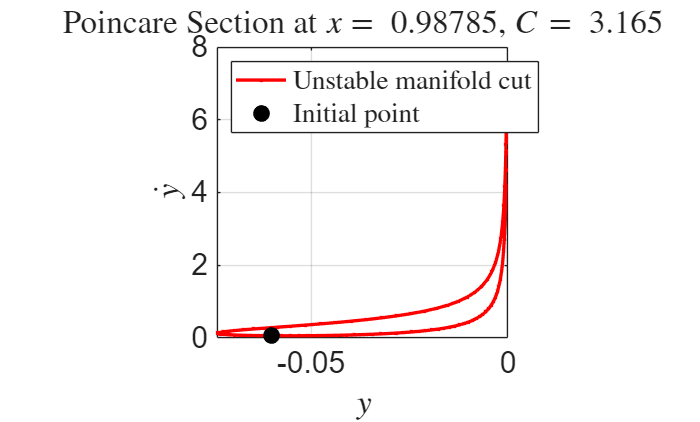

x0    =  x_poincare ;
y0    = -0.06  ;
ydot0 =  0.058  ;

xd_sign = 1;
xdot0 = dot_from_x_y_dot(x0,y0,ydot0,C,xd_sign);

X0 = [x0 y0 xdot0 ydot0] ;

% slightly larger than the time to reach the Poincare section
tfinal = 3 ;

figure
% Poincare section
if Poincare_XY_const == 1
    h1=plot(xsos,xdsos,manifold_color,'linewidth',2);
    title(['Poincare Section at y = 0, C = ', num2str(C,'%0.3g')], 'FontSize', 18);
    hold on
    h2=plot(x0,xdot0,'k.','markersize',30,'DisplayName','Initial point');
    xlabel('$x$', 'Interpreter', 'latex'); 
    ylabel('$\dot{x}$', 'Interpreter', 'latex')

elseif Poincare_XY_const == 2
    h1=plot(ysos,ydsos,[manifold_color '.-'],'linewidth',2,'DisplayName', [manifold_title ' manifold cut']);
    title(['Poincare Section at $x =$ ', num2str(x_poincare,'%0.5g'),', $C =$ ', num2str(C,'%0.12g')], ...
        'FontSize', 18,'Interpreter','latex');
    hold on
    h2=plot(y0,ydot0,'k.','markersize',30,'DisplayName','Initial point');
    xlabel('$y$', 'Interpreter', 'latex'); 
    ylabel('$\dot{y}$', 'Interpreter', 'latex')

elseif Poincare_XY_const == 3
    plot(xsos,ysos,'k-',xsos(k),ysos(k),'ro','linewidth',2);
    xlabel('x'); ylabel('y');
    title(['Poincare Section at perigee, C = ', num2str(C,'%0.3g')], 'FontSize', 18);
    legend('Stable manifold cut','location','northwest');
end
legend([h1 h2],'location','northwest','Interpreter','latex');
set(gca,'fontsize',18)
grid on
axis square
hold off

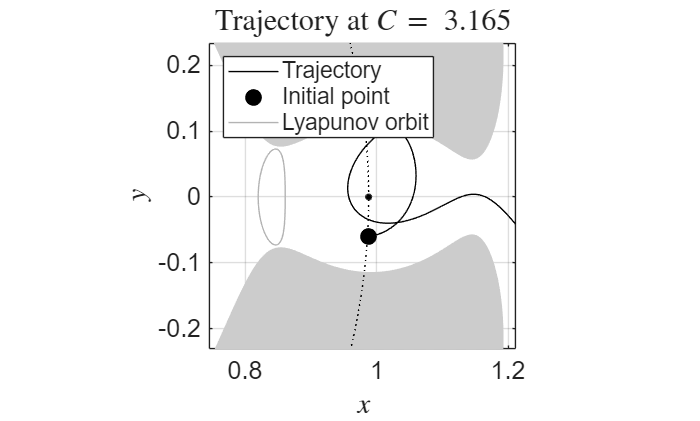


tol = 1e-10;
opts = odeset('AbsTol',tol,'RelTol',3*tol);
[t,x] = ode45(@(t,X) prtbp(t,X), [0 tfinal], X0, opts) ;

figure
plot(x(:,1),x(:,2),'k',x(1,1),x(1,2),'k.','markersize',30);
hold on
plot(X(:,1),X(:,2),'color',[0.7 0.7 0.7]); % plot initial periodic orbit

% plot zero velocity curve
% Define level set value
level_value = -C/2; % Adjust based on the desired level set

if level_value < max(Ubar(:)) % can only plot forbidden realm if E < E_L4
    % Plot filled contour in gray
    contourf(xx, yy, Ubar, [level_value, max(Ubar(:))], 'LineColor', 'none');
    colormap(0.8*[1 1 1]); % Set colormap to gray
    clim([level_value, max(Ubar(:))]); % Fix color scale
end

earthmun % plot Earth, Moon and Moon's orbit to scale, remove if not Earth-Moon system
hold off
grid on
axis equal
set(gca,'fontsize',15)
title(['Trajectory at $C =$ ', num2str(C,'%0.4g')], 'FontSize', 18,'Interpreter', 'latex');
xlabel('$x$', 'Interpreter', 'latex'); 
ylabel('$y$', 'Interpreter', 'latex'); 

legend('Trajectory','Initial point','Lyapunov orbit','location','northwest');

xlim([0.746 1.211])
ylim([-0.231 0.234])

## FUNCTIONS

function ydot = ydot_from_x(x,C,pos)
% Computation of new ydot value
global mu

if nargin < 3
    pos = sign(C);
    if pos == -1
        C = -C ;
    end
end

% Gravitational parameter calculations
mu1=1-mu;
mu2=  mu;

U = -1/2*x^2 - mu1/sqrt((x+mu2)^2)-mu2/sqrt((x-mu1)^2); 
ydot = (-C-2*U)^(1/2);

if pos==-1
    ydot =-ydot;
end

end
%%%%%%%%%%%%%%%%%%%%%

function ydot = ydot_from_x_xdot(x,xdot,C,pos)
% Computation of new ydot value
global mu

if nargin < 3
    pos = sign(C);
    if pos == -1
        C = -C ;
    end
end

% Gravitational parameter calculations
mu1=1-mu;
mu2=  mu;

U = -1/2*x^2 - mu1/sqrt((x+mu2)^2)-mu2/sqrt((x-mu1)^2); 
ydot = (-C -2*U - xdot^2)^(1/2);

if pos==-1
    ydot =-ydot;
end

end
%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%

function xdot = dot_from_x_y_dot(x,y,ydot,C,pos)
% Computation of new whatever-dot value
global mu

if nargin < 4
    pos = sign(C);
    if pos == -1
        C = -C ;
    end
end

% Gravitational parameter calculations
mu1=1-mu;
mu2=  mu;

Ubar = -1/2*(x^2+y^2) - mu1/sqrt((x+mu2)^2+y^2)-mu2/sqrt((x-mu1)^2+y^2); 
xdot = (-C -2*Ubar - ydot^2)^(1/2);

if pos==-1
    xdot =-xdot;
end

end
%%%%%%%%%%%%%%%%%%%%%


function l = cartesian_to_mean_anomaly_batch(s, ~)
%Cartesian barycentered planar synodic position-velocity to m1-centered mean anomaly
global mu
    x=s(:,1);
    y=s(:,2);
    px=s(:,3)-s(:,2); %Convert to barycentered interial frame momenta
    py=s(:,4)+s(:,1); %Convert to barycentered interial frame momenta
    pos = [x + mu,y]; %Barycentered frame position x,y
    vel = [px,py+mu]; %Barycentered inertial frame momenta px, py

%    pos = pos - [-mu, 0]; %m1 centered frame position
%    vel = mom + [0 , mu]; %m1 centered nonrotating frame velocity

    GM=1-mu;

    r=vecnorm(pos')'; v=vecnorm(vel')';
    e_vec=(v.^2/GM-1./r).*pos-(dot(pos', vel')'/GM).*vel;
    e=vecnorm(e_vec')';

    size(e_vec)
    size(pos)
    for k = 1:length(s)
    if dot(vel(k,:), pos(k,:))>=0
        true_anomaly(k) =        acos(max(min(dot(e_vec(k,:)/e(k), pos(k,:)/r), 1), -1));
    else
        true_anomaly(k) = 2*pi - acos(max(min(dot(e_vec(k,:)/e(k), pos(k,:)/r), 1), -1));
    end

    f(k,1) = real(true_anomaly(k));
    u(k,1)=acos(max(min((e(k)+cos(f(k)))/(1+e(k)*cos(f(k))), 1), -1));
    if f(k)>pi
        u(k)=2*pi-u(k);
    end

    l(k) = u(k) - e(k)* sin(u(k));
    end
end

%%%%%%%%%%%%%%%%%%%%%
 
function C = Jconst(X)
    % Function calculates Jacobi constant given a state
    x = X(1); 
    y = X(2);
    xdot = X(3); 
    ydot = X(4);

    mu = 0.012150584270572;
    mu1=1-mu;
    mu2=  mu;

    r1 = ((x+mu2)^2 + y^2)^(1/2);
    r2 = ((x-mu1)^2 + y^2)^(1/2);
    
    U = -1/2*(x^2+y^2)-mu1/r1-mu2/r2; %-1/2*mu1*mu2;
    
    C = -(xdot^2 + ydot^2)-2*U;
end

%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Differential Correction function

function [x0,t1] = differential_corrector_symmetric(x0g,t_min,show)
% [x0,t1]=differential_corrector_symmetric(x0g,t_min,show)
%
% This is the differential correction routine to create planar periodic 
% Liapunov orbits about L1,L2, or L3 in the CR3BP. It keeps the initial 
% x value constant and varies the y-velocity value.
%
% output: x0  = initial state on the Liapunov (on the xz-plane) in nondim.
%		CR3BP coords.
%	  t1  = half-period of Liapunov orbit in nondim. CR3BP time 
%
% input: x0g  = first guess of initial state on a symmetric periodic orbit
%        t_min 
%	 show = 1 to plot successive orbit  (default=0)
%
%-------------------------------------------------------------------------
% CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
% -L3----m1--+-------L1--m2--L2-
%                L5
%
% Shane Ross (revised 6.20.24)
global mu

if nargin < 3 
    show = 0 ;
    if nargin < 2
        t_min = pi/2-.15 ;
    end
end

MAXdxdot1 = 1.e-12; % measure of precision of perpendicular x-axis crossing
MAXattempt=45;

t0 = 0;
dxdot1 = 1;
attempt = 0;

while abs(dxdot1) >  MAXdxdot1
	if attempt > MAXattempt
		ERROR = 'MAX attempts exceeded'
		break
	end
		
	[t1,xx1]=find0(x0g,t_min); % find x-axis crossing near the original

    x1     = xx1(1); y1    = xx1(2);
    dxdot1 = xx1(3); ydot1 = xx1(4);

    [x,t,phi_t1,PHI]=PHIget(x0g,t1);

    if show==1
        a = 1 ;
        plot(x(:,1),x(:,2));
        plot(a*x(1,1),a*x(1,2),'wo');
        axis([min(x(:,1)) max(x(:,1)) min(x(:,2)) max(x(:,2))]);
        axis('equal');
        hold on
    end

	mu2 = 1 - mu;
	r1 = ((x1+mu)^2  + y1^2 );
	r2 = ((x1-mu2)^2 + y1^2 );
	rho1=1/r1^1.5;
	rho2=1/r2^1.5;
	
	omgx1=-(mu2*(x1+mu)*rho1) -(mu*(x1-mu2)*rho2) + x1;

	xdotdot1 = (2*ydot1 + omgx1);

    damping = 0.5 ;
	C1 = phi_t1(3,4);
	C2 = phi_t1(2,4);
	C3 = (C1 - (1/ydot1)*xdotdot1*C2);
	C4 = -dxdot1/C3 ;
	dydot0 = damping*C4;

	x0g(4) = x0g(4) + dydot0;

    attempt=attempt+1 ;
    % Display progress
    disp(['Attempt: ', num2str(attempt,'%d'), ...
    ' vx1: ', num2str(dxdot1,'%0.3e')]);
end
x0=x0g;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [value,isterminal,direction] = apse_crossing(t,x) 
global t_wait direction_global mu

% wait the required amount of time
if abs(t) > t_wait
    isterminal = 1;  %terminate after waiting for a short time and x > 1-mu
else
    isterminal = 0;
end

r1_dot_times_r1 = (x(1) + mu)*x(3) + x(2)*x(4) ;

% we want cosine of the angle between the position and 
% velocity vectors in the m1-centered non-rotating frame,
% which is a perigee (direction = -1) or apogee (direction = 1)
%value = dot([x(1)+mu,x(2)], [x(3)-x(2),x(4)+x(1)+mu])  ; 
value = r1_dot_times_r1  ; 

% 0 = doesn't matter 
%-1 = if 'value' decreasing 
% 1 = if 'value' increasing 
direction = direction_global ; 

end   

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [value, isterminal, direction] = poincare_event_func(t, s)
global t_wait direction_global mu

% wait the required amount of time
if abs(t) > t_wait
    isterminal = 1;  %terminate after waiting for a short time
else
    isterminal = 0;
end

l = cartesian_to_mean_anomaly(s,t);
p= cos(l)+0.25*sin(l)-1;
%a = -cos(l)-0.25*sin(l)-1;
%value = dot([x+mu,y], [px, py+mu])/(norm([x+mu,y])*norm([px, py+mu])); % TODO: FILL IN THE EQUATION, s(2) is y, so this event is flagged when y = 0
%value = a;
value = p ;
%    isterminal = terminate;    % event is triggered when value: y = 0. If integration has to terminate at this event put =1
direction = direction_global;     % =0 if all events to be captured, -1 if value is decreasing and 1 if increasing

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function l = cartesian_to_mean_anomaly(s,t)
%Cartesian barycentered planar synodic position-velocity to m1-centered mean anomaly
global mu
    x=s(1);
    y=s(2);
    px=s(3)-s(2); %Convert to barycentered inertial frame momenta
    py=s(4)+s(1); %Convert to barycentered inertial frame momenta
    pos = [x,y];  %Barycentered frame position x,y
    mom = [px,py];%Barycentered inertial frame momenta px, py

    pos = pos - [-mu, 0]; %m1 centered frame position
    vel = mom + [0, mu]; %m1 centered nonrotating frame velocity

    GM=1-mu;

    r=norm(pos); v=norm(vel);
    e_vec=(v^2/GM-1/r)*pos-(dot(pos, vel)/GM)*vel;
   
    e=norm(e_vec);

    if dot(vel, pos) >= 0
        true_anomaly =        acos(dot(e_vec/e, pos/r));
    else
        true_anomaly = 2*pi - acos(dot(e_vec/e, pos/r));
    end

    f = real(true_anomaly);             % True Anomaly
    u=acos((e+cos(f))/(1+e*cos(f)));    % Eccentric Anomaly
    if f>pi
        u=2*pi-u;
    end
   
    l = u - e * sin(u);                 % Mean Anomaly

    if l > pi           % to have continuity at l=0
        l = l - 2*pi ; 
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function l = cartesian_to_mean_anomaly_X(X,t)
%Cartesian barycentered planar synodic position-velocity to m1-centered mean anomaly
global mu
    % x=s(1);
    % y=s(2);
    % px=s(3)-s(2); %Convert to barycentered inertial frame momenta
    % py=s(4)+s(1); %Convert to barycentered inertial frame momenta
    % pos = [x,y];  %Barycentered frame position x,y
    % mom = [px,py];%Barycentered inertial frame momenta px, py
    % 
    % pos = pos - [-mu, 0]; %m1 centered frame position
    % vel = mom + [0, mu]; %m1 centered nonrotating frame velocity

    %Xin = rot2iner(s,t,1,mu); % get from rot2iner

    d= -mu; 	% distance to LARGER  primary in CR3BP (M1)

    c=cos(t); s=sin(t);

    Xin=[];
    Xin(1)= c*(X(1)-d) - s*X(2);
    Xin(2)= s*(X(1)-d) + c*X(2);
    Xin(3)=-s*(X(1)+X(4)-d) + c*(X(3) - X(2));
    Xin(4)= c*(X(1)+X(4)-d) + s*(X(3) - X(2));

    pos = Xin(1:2)';
    vel = Xin(3:4)';

    GM=1-mu;

    r=norm(pos); v=norm(vel);
    %e_vec=(v^2/GM-1/r)*pos-(dot(pos, vel)/GM)*vel;

%% A different way
    h = pos(1)*vel(2) - pos(2)*vel(1) ;

    v_cross_h = [ vel(2)*h ; -vel(1)*h ] ;
    e_vec=(1/GM)* v_cross_h - pos/r ;
   
    e=norm(e_vec);

    if dot(vel, pos) >= 0
        true_anomaly =        acos(dot(e_vec/e, pos/r));
    else
        true_anomaly = 2*pi - acos(dot(e_vec/e, pos/r));
    end

    f = real(true_anomaly);             % True Anomaly
    u=acos((e+cos(f))/(1+e*cos(f)));    % Eccentric Anomaly
    if f>pi
        u=2*pi-u;
    end
   
    l = u - e * sin(u);                 % Mean Anomaly

    if l > pi
        l = l - 2*pi ;
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [value,isterminal,direction] = x_axis_crossing(t,x) 
global t_wait primary_section direction_global

if primary_section == 2 % U2
    if x(1) > 1 - 0.012150584270572 && abs(t) > t_wait
        isterminal = 1;  %terminate after waiting for a short time and x > 1-mu
    else
        isterminal = 0;
    end
elseif primary_section == 1  % U1
    if x(1) < -0.012150584270572 && abs(t) > t_wait
        isterminal = 1;  %terminate after waiting for a short time and x < 1-mu
    else
        isterminal = 0;
    end
elseif primary_section == 3
    if abs(t) > t_wait
        isterminal = 1;  %terminate after waiting for a short time and x > 1-mu
    else
        isterminal = 0;
    end    
end

value = x(2) ; % x(2) = y, so we want y = value = 0, an x-axis crossing

% 0 = doesn't matter if 'value' decreasing (-1) or increasing (+1)
direction = direction_global ; 

end   

%%%%%%%%%%%%

function [value, isterminal, direction] = y_axis_crossing(t, x)
    global t_wait x_poincare direction_global

    % Event 1: x = x_poincare AND past wait time → record crossing
    if abs(t) > t_wait % && x(2) > 0
        value(1) = x(1) - x_poincare;  % crossing of Poincaré section
    else
        value(1) = 1;  % ensure it's not triggered
    end
    isterminal(1) = 1;            %  stop integration
    direction(1)  = direction_global;

    % Event 2: x = -0.1 → stop integration
    value(2) = x(1) + 0.1;
    isterminal(2) = 1;            % stop integration
    direction(2)  = 0;            % detect crossing from any direction
end

%%%%%%%%%%%%%%%%%%%%%%

function xdot = prtbp(~,x)
% xdot = prtbp(t,x)
%
% with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
%
% -L3----m1--+-------L1--m2--L2-
%
%                L5
%
% Shane Ross (revised 9.23.97)
global mu

mu1=1-mu; % mass of larger  primary (nearest origin on left)
mu2=  mu; % mass of smaller primary (furthest from origin on right)

r3= ((x(1)+mu2)^2 + x(2)^2)^1.5;     % r: distance to m1, LARGER MASS
R3= ((x(1)-mu1)^2 + x(2)^2)^1.5;     % R: distance to m2, smaller mass

xdot    = zeros(4,1);
xdot(1) = x(3);
xdot(2) = x(4);
xdot(3) = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3)+2*x(4);
xdot(4) = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3)-2*x(3);
end

%%%%%%%%%%%%%%%%%%%%
%% Compute 3-Body Energy

function E = energy(X,mu,include_constant)
% include_constant = 0 or 1

if nargin == 2
    include_constant = 0 ; % exclude constant by default
end

% parameters; masses/locations of m1,m2 in non-dimensional units
mu1=1-mu;
mu2=mu;

if size(X,2) >= 5 % if 3 degree of freedom (spatial) system
    % velocity in rotating frame, squared
    Vsqrd= X(:,4).^2 + X(:,5).^2 + X(:,6).^2 ;
    % Effective potential
    Ubar = - mu1./sqrt((X(:,1)+mu2).^2 + X(:,2).^2 + X(:,3).^2) ...
           - mu2./sqrt((X(:,1)-mu1).^2 + X(:,2).^2 + X(:,3).^2) ...    
           - 0.5*(X(:,1).^2+X(:,2).^2) - 0.5*mu1*mu2*include_constant ;
else % if 2 degree of freedom (planar) system
    % velocity in rotating frame, squared
    Vsqrd= X(:,3).^2 + X(:,4).^2 ;
    % Effective potential    
    Ubar = - mu1./sqrt((X(:,1)+mu2).^2 + X(:,2).^2) ...
           - mu2./sqrt((X(:,1)-mu1).^2 + X(:,2).^2) ...
           - 0.5*(X(:,1).^2+X(:,2).^2) - 0.5*mu1*mu2*include_constant ;
end

E = 0.5*Vsqrd + Ubar ;

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function Xin = rot2iner(X,t,M,mu,del)
% Xin=rot2iner(X,T,M,mu,del);
%
% Transformation from M body-centered rotating (nondim.) coordinates to
% inertial (nondim.) coordinates
%
% M = 2 : smaller mass(M2) centered inertial coordinates
% M = 1 : LARGER  mass(M1) centered inertial coordinates
% M = 0 : center-of-mass   centered inertial coordinates
%
% X   = state 4- or 6-vector matrix (in nondim. rotating coordinates)
% t   = nondimensional CR3BP time
% del = the rotation offset at time t=0 (in radians)
%
% Xrot = inv(B)*(Xin - A)
% see p.6 of Cassall(1996)
%
% NOTE: nondim. means nondimensional CR3BP units where 
%	sum of primaries' mass = 1
%	constant distance between primaries = 1
%	period of primaries' orbit = 2*pi
% 
%-----------------------------------------------------------------------
% CR3BP (Circular Restricted Three-Body [Gravitational] Problem)
% with the LARGER MASS, M1 to the left of the origin at (-mu,0)
% and the smaller mass, M2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%       (rotating coords)
%
%                 L4
% -L3------M1--+-----L1--M2--L2-
%                 L5
%
% Shane Ross (revised 7.15.97)
%

% Defaults
if nargin<=4
    del=0;
    if nargin<=3
        mu=0;
        if nargin<=2
            M=0;
        end
    end
end

if     M==1, d= -mu; 	% distance to LARGER  primary in CR3BP (M1)
elseif M==2, d=1-mu;	% distance to smaller primary in CR3BP (M2)
elseif M==0, d=0;	    % center-of-mass is the origin
end

c=cos(t + del); s=sin(t + del);

Xin=[];
Xin(:,1)= c.*(X(:,1)-d) - s.*X(:,2);
Xin(:,2)= s.*(X(:,1)-d) + c.*X(:,2);
Xin(:,3)=-s.*(X(:,1)+X(:,4)-d) + c.*(X(:,3) - X(:,2));
Xin(:,4)= c.*(X(:,1)+X(:,4)-d) + s.*(X(:,3) - X(:,2));

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Differential Correction function

function [x0,t1] = liadifcor(x0g,MAXdxdot1,show)
% [x0,t1]=liadifcor(x0g,show)
%
% This is the differential correction routine to create planar periodic 
% Liapunov orbits about L1,L2, or L3 in the CR3BP. It keeps the initial 
% x value constant and varies the y-velocity value.
%
% output: x0  = initial state on the Liapunov (on the xz-plane) in nondim.
%		CR3BP coords.
%	      t1  = half-period of Liapunov orbit in nondim. CR3BP time 
%
% input: x0g  = first guess of initial state on the Liapunov orbit
%        MAXdxdot1 = 1.e-12; % measure of precision of perpendicular x-axis crossing
%	     show = 1 to plot successive orbit  (default=0)
%
%-------------------------------------------------------------------------
% CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
% -L3----m1--+-------L1--m2--L2-
%                L5
%
% Shane Ross (revised 7.2.24)
global mu

if nargin < 3
    show = 0; % do not plot
    if nargin < 2 
        MAXdxdot1 = 1.e-12; % measure of precision of perpendicular x-axis crossing
    end
end

t0 = 0;
dxdot1 = 1;
attempt = 0;
MAXattempt=25;

while abs(dxdot1) >  MAXdxdot1
	if attempt > MAXattempt
        % Display error
        disp(['ERROR, MAXattempt exceeded']);
		break
    end

    attempt=attempt+1 ;
    % Display total area (non-dimensional)
    disp(['Attempt ', num2str(attempt,'%0.1g'), ...
    ' |vx1| ', num2str(abs(dxdot1),'%0.3e')]);
    
    % find x-axis crossing
	[t1,xx1]=find0(x0g); 

    x1     = xx1(1); y1    = xx1(2);
    dxdot1 = xx1(3); ydot1 = xx1(4);
 
    % dxdot1 
    [x,t,phi_t1,PHI]=PHIget(x0g,t1);

    if show==1
        plotX(x);
        plot(a*x(1,1),a*x(1,2),'wo');
        axis([min(x(:,1)) max(x(:,1)) min(x(:,2)) max(x(:,2))]);
        axis('equal');
    end

	mu2 = 1 - mu;
	r1 = ((x1+mu )^2 + y1^2 );
	r2 = ((x1-mu2)^2 + y1^2 );
	rho1=1/r1^1.5;
	rho2=1/r2^1.5;
	
	omgx1=-(mu2*(x1+mu)*rho1) -(mu*(x1-mu2)*rho2) + x1;

	xdotdot1 = (2*ydot1 + omgx1);

	C1 = phi_t1(3,4);
	C2 = phi_t1(2,4);
	C3 = (C1 - (1/ydot1)*xdotdot1*C2);
	C4 = inv(C3)*dxdot1;
	dydot0 = C4;
    
    % vy0 \mapsto vy0    - \delta vy0    
	x0g(4)    =   x0g(4) - dydot0;

end
x0=x0g;

end

%
%% Differential Correction function

function [x0,t1] = liadifcor_C(x0g,C,t_min,MAXdxdot1,show)
% [x0,t1]=liadifcor_C(x0g,C,t_min,MAXdxdot1,show)
%
% This is the differential correction routine to create planar periodic 
% Liapunov orbits about L1,L2, or L3 in the CR3BP. It keeps the Jacobi  
% constant value C fixed and varies the initial x position.
%
% output: x0  = initial state on the Liapunov (on the xz-plane) in nondim.
%		CR3BP coords.
%	      t1  = half-period of Liapunov orbit in nondim. CR3BP time 
%
% input: x0g  = first guess of initial state on the Liapunov orbit
%        C    = Jacobi constant 
%        t_min= finds the next x-crossing of a trajectory
%               after time t_min
%        MAXdxdot1 (default 1.e-12) = measure of precision of 
%                                     perpendicular x-axis crossing
%	     show = 1 to plot successive orbit  (default=0)
%
%-------------------------------------------------------------------------
% CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
% -L3----m1--+-------L1--m2--L2-
%                L5
%
% Shane Ross (revised 7.3.24)
global mu FORWARD 

FORWARD = 1 ; % Needs to be going forward for some reason

if nargin < 5
    show = 0; % do not plot
    if nargin < 4
        MAXdxdot1 = 1.e-12; % measure of precision of perpendicular x-axis crossing
        if nargin < 3
            t_min = pi/2-.15 ; % works for Lyapunov orbits around L1
        end
    end
end

t0 = 0;
vx1 = 1;
attempt = 0;
MAXattempt=25;

pos = sign(x0g(4)) ;

while abs(vx1) >  MAXdxdot1
	if attempt > MAXattempt
        disp('ERROR, MAX attempts exceeded');
		break
	end

    x0     = x0g(1); 
    y0     = x0g(2);
    vx0    = x0g(3); 
    vy0    = x0g(4);
		
    % find x-axis crossing after waiting for t_min
	[t1,xx1]=find0(x0g,t_min); 
 
    x1     = xx1(1); 
    y1     = xx1(2);
    vx1    = xx1(3); 
    vy1    = xx1(4);

    % dxdot1 
    [x,t,phi_t1,PHI]=PHIget(x0g,t1);

    if show==1
        plotX(x);
        plot(x(1,1),x(1,2),'wo');
        axis([min(x(:,1)) max(x(:,1)) min(x(:,2)) max(x(:,2))]);
        axis('equal');
    end

	mu2 = 1 - mu;
	r1 = ((x1+mu )^2 + y1^2 );
	r2 = ((x1-mu2)^2 + y1^2 );
	rho1=1/r1^1.5;
	rho2=1/r2^1.5;

    r10 = ((x0+mu )^2 + y0^2 );
	r20 = ((x0-mu2)^2 + y0^2 );
	rho10=1/r10^1.5;
	rho20=1/r20^1.5;

    % partial derivatives of effective potential U
	Ux0 = (mu2*(x0+mu)*rho10) + (mu*(x0-mu2)*rho20) - x0;

    Ux1 = (mu2*(x1+mu)*rho1 ) + (mu*(x1-mu2)*rho2 ) - x1;

	vx1dot = (2*vy1 - Ux1);

    phi21 = phi_t1(2,1);
    phi24 = phi_t1(2,4);
    phi31 = phi_t1(3,1);
    phi34 = phi_t1(3,4);

    A =-Ux0/vy0 ;
    B = vy1/(vx1dot*phi21) ;

    dum1 = 1 + A*phi24/phi21 ...
           -B*(phi31+phi34*A) ; 
    dum  = -B*vx1/dum1 ;

	delta_x0 = dum ;
    
    % x0 \mapsto x0    - \delta x0    
	x0g(1) =     x0g(1) - delta_x0 ;

    x0g(4) = ydot_from_x(x0g(1),C,pos) ;

    attempt=attempt+1 ;
    % Display progress
    disp(['Attempt: ', num2str(attempt,'%d'), ...
    ' vx1: ', num2str(vx1,'%0.3e')]);
end

% return once threshold tolerance reached
x0=x0g;

end


%% Compute the state transition matrix

function [x,t,phi_tf,PHI]=PHIget_span(x0,tspan)
% [x,t,phi_tf,PHI]=PHIget_span(x0,tspan)
% 
% Gets state transition matrix, phi_tf, and the trajectory (x,t) for 
% along a time-span tspan (in nondimensional time where 2*pi is 1 period). 
% 
% e.g., tspan = [ 0 tf]
%   or  tspan = linspace(0,tf,n), where n is the number of points along the
%               trajectory one wants evaluated
%
% In particular, for periodic solutions of period T, one can obtain 
% the monodromy matrix, PHI(0,T).
%
% Shane Ross (revised 7.2.24)
global tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

N=length(x0);

PHI_0(1:N^2) 	   = reshape(eye(N),N^2,1);
PHI_0(1+N^2:N+N^2) = x0;

if     N==4 
    [t,PHI] = ode113(@(t,PHI) var2D(t,PHI), tspan, PHI_0, OPTIONS);
elseif N==6 
    [t,PHI] = ode113(@(t,PHI) var3D(t,PHI), tspan, PHI_0, OPTIONS); 
end

x = PHI(:,1+N^2:N+N^2); % trajectory

% state transition matrix at final time PHI(O,tf)
phi_tf = reshape(PHI(length(t),1:N^2),N,N); 

end


%% For planar CR3BP, the variational equations

function PHIdot = var2D(t,PHI)
% PHIdot=var2D(t,PHI)
%
% This here is a preliminary state transition, PHI(t,t0),
% matrix equation attempt for the planar CR3BP, based on...
%
%        d PHI(t, t0)
%        ------------ =  F(t) * PHI(t, t0)
%             dt
%
%-----------------------------------------------------------
% CR3BP CONVENTION:
%                 L4
%
%
%    L3-----M1-------L1---M2---L2         M1=1-mu, M2=mu
%
%
%                 L5
%
% Shane Ross (revised 9.23.97)
%
% global FORWARD mu
global FORWARD mu

mu1=1-mu;
mu2=  mu;

x(1:4) = PHI(17:20);
phi  = reshape(PHI(1:16),4,4);

r2= (x(1)+mu )^2 + x(2)^2;	% r: distance to m1, LARGER MASS
R2= (x(1)-mu1)^2 + x(2)^2;	% R: distance to m2, smaller mass
r3= r2^1.5; r5= r2^2.5;
R3= R2^1.5; R5= R2^2.5;

omgxx= 1+(mu1/r5)*(3*(x(1)+mu2)^2)+(mu2/R5)*(3*(x(1)-mu1)^2)-(mu1/r3+mu2/R3);
omgyy= 1+(mu1/r5)*(3* x(2)^2     )+(mu2/R5)*(3* x(2)^2     )-(mu1/r3+mu2/R3);
omgxy= 3*x(2)*     (mu1*(x(1)+mu2)/r5+mu2*(x(1)-mu1)/R5); 

	F     =[   0     0     1     0  ; 
	           0     0     0     1  ; 
		     omgxx omgxy   0     2  ; 
         	 omgxy omgyy  -2     0 ];

phidot = F * phi; % variational equation

PHIdot        = zeros(20,1);
PHIdot(1:16)  = reshape(phidot,16,1);
PHIdot(17)    = x(3);
PHIdot(18)    = x(4);
PHIdot(19)    = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3) + 2*x(4);
PHIdot(20)    = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3) - 2*x(3);
PHIdot(17:20) = FORWARD*PHIdot(17:20);

end

%%

function [PHIdot] = var3D(t,PHI)
% function [PHIdot]=var3D(t,PHI);
%
% This here is a preliminary state transition, PHI(t,t0),
% matrix equation attempt for the CR3BP, based on...
%
%        d PHI(t, t0)
%        ------------ =  F(t) * PHI(t, t0)
%             dt
%
%  CONVENTION
%
%                 L4
%
%    L3-----M1-------L1---M2---L2         M1=1-mu, M2=mu
%
%                 L5
% Shane Ross (revised 7.1.97)
%
% global mu FORWARD
global mu FORWARD
 
mu2 = 1-mu;
x(1:6) = PHI(37:42);
phi  = reshape(PHI(1:36), 6, 6);

r2= (x(1)+mu )^2 + x(2)^2 + x(3)^2;	% r: distance to m1, LARGER MASS
R2= (x(1)-mu2)^2 + x(2)^2 + x(3)^2;	% R: distance to m2, smaller mass
r3= r2^1.5; r5= r2^2.5;
R3= R2^1.5; R5= R2^2.5;

omgxx= 1+(mu2/r5)*(3*(x(1)+mu)^2)+(mu/R5)*(3*(x(1)-mu2)^2)-(mu2/r3+mu/R3);
omgyy= 1+(mu2/r5)*(3* x(2)^2    )+(mu/R5)*(3* x(2)^2     )-(mu2/r3+mu/R3);
omgzz=   (mu2/r5)*(3* x(3)^2    )+(mu/R5)*(3* x(3)^2     )-(mu2/r3+mu/R3);

omgxy= 3*x(2)*     (mu2*(x(1)+mu)/r5+mu*(x(1)-mu2)/R5); 
omgxz= 3*x(3)*     (mu2*(x(1)+mu)/r5+mu*(x(1)-mu2)/R5); 
omgyz= 3*x(2)*x(3)*(mu2          /r5+mu           /R5);

	F     =[   0     0     0     1     0	 0 ; 
	           0     0     0     0 	   1 	 0 ; 
        	   0	 0     0     0     0     1 ;
		    omgxx omgxy omgxz    0     2 	 0 ; 
         	omgxy omgyy omgyz   -2     0 	 0 ;
		    omgxz omgyz omgzz    0	   0	 0 ];

phidot = F * phi;

PHIdot        = zeros(42,1);
PHIdot(1:36)  = reshape(phidot, 36, 1);
PHIdot(37)    = x(4);
PHIdot(38)    = x(5);
PHIdot(39)    = x(6);
PHIdot(40)    = x(1)-(mu2*(x(1)+mu)/r3) -(mu*(x(1)-mu2)/R3) + 2*x(5);
PHIdot(41)    = x(2)-(mu2* x(2)    /r3) -(mu* x(2)     /R3) - 2*x(4);
PHIdot(42)    =     -(mu2* x(3)    /r3) -(mu* x(3)     /R3);
PHIdot(37:42) = PHIdot(37:42)*FORWARD;

%omgx = x(1)-(mu2*(x(1)+mu)/r3) -(mu*(x(1)-mu2)/R3);
%omgy = x(2)-(mu2* x(2)    /r3) -(mu* x(2)     /R3);
%omgz =     -(mu2* x(3)    /r3) -(mu* x(3)     /R3);
%PHIdot(40) = FORWARD * ( omgx+2*x(5) );
%PHIdot(41) = FORWARD * ( omgy-2*x(4) );
%PHIdot(42) = FORWARD *   omgz;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Find an x-axis crossing

function [t1_z,x1_z]=find0(x0,t_min)
% function [t1_z,x1_z]=find0(x0,t_min)
%
% From the given state x0, this finds the next x-crossing of a trajectory
% after time t_min
global t0_z x0_z x1_zgl

tolzero = 1.e-10;
options = optimset('DiffMaxChange',tolzero,'TolCon',tolzero,'TolFun',tolzero) ;

if nargin == 1
    t_min = pi/2-.15;
end
t0_z = t_min ; % only look for x-axis crossings after this time
[xx,~] = int(x0,t0_z);
x0_z=xx(end,:);
t1_z=fzero(@haloy,t0_z,options);
x1_z = x1_zgl;

clear global t0_z x0_z x1_zgl

end


%%%%%%%%%%%%%%%%%%%%%%

% Integrate ODEs

function [x,t] = int(x0,tf)
% function [x,t]=int(x0,tf)
%    Integrate x w/ initial condition x0 from time 0 to tf
%
% Shane Ross (revised 7.3.24)
%
% Uses MATLAB's Built-In ode113 function
%
% global tol
global tol %FORWARD tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

t0=0;
m=length(x0);

if     m==3	% surface of section--planar equations of motion integrated
	[t,x] = ode113(@(t,x) prtbp(t,x), [t0 tf],[x0(1) 0 x0(2) x0(3)],OPTIONS);
elseif m==4	% planar equations of motion integrated
    [t,x] = ode113(@(t,x) prtbp(t,x), [t0 tf], x0, OPTIONS) ;
elseif m==6	% 3D     equations of motion integrated
	[t,x] = ode113(@(t,x)  rtbp(t,x), [t0 tf], x0, OPTIONS) ;
end
%t=FORWARD*t;	% for backwards integration, time is like a countdown
% this is now handled automatically by ode45 and ode113 depending on
% the sign of tf

end

%%%%%%%%%%%%%%%%%%%%%%%%

function xdot = rtbp(t,x)
% xdot = rtbp(t,x);
%
% with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
% -L3----m1--+-----L1--m2--L2-
%                L5
%
% Shane Ross (revised 9.23.97)
%
% global mu FORWARD
%           FORWARD = +1 for forward  integration
%  	              -1 for backward integration 
global mu FORWARD

mu1 = 1-mu; % mass of larger  primary (nearest origin on left)
mu2 =   mu; % mass of smaller primary (furthest from origin on right)

r3= ((x(1)+mu2)^2 + x(2)^2 + x(3)^2)^1.5;     % r: distance to m1, LARGER MASS
R3= ((x(1)-mu1)^2 + x(2)^2 + x(3)^2)^1.5;     % R: distance to m2, smaller mass

%omgx = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3);
%omgy = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3);
%omgz =     -(mu1* x(3)     /r3) -(mu2* x(3)     /R3);
%xdot(4) = ( omgx+2*x(5) );
%xdot(5) = ( omgy-2*x(4) );
%xdot(6) =   omgz;

xdot = zeros(6,1);
xdot(1) = x(4);
xdot(2) = x(5);
xdot(3) = x(6);
xdot(4) = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3) + 2*x(5);
xdot(5) = x(2)-(mu1* x(2)    /r3)  -(mu2* x(2)     /R3) - 2*x(4);
xdot(6) =     -(mu1* x(3)    /r3)  -(mu2* x(3)     /R3);
xdot    = FORWARD * xdot;

end

%%

function y1=haloy(t1)
% haloy.m computes the y-position of the halo orbit at time t.
global t0_z x0_z x1_zgl

if t1==t0_z
   x1_zgl = x0_z ; 
else
    [xx,tt]=intDT(x0_z,t0_z,t1);
    x1_zgl=xx(end,:);
end
y1    =x1_zgl(2);
end

%%

function  [x,t] = intDT(x0,t0,tf)
% [x,t] = intDT(x0,t0,tf,tol)
%
% Integrates for an interval (i.e., a 'dt') shorter than the total time of  
% data desired.
%
% Integrate x w/ initial condition x0 from time t0 to tf
%
% global FORWARD tol

global FORWARD tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

m=length(x0);

if m==4,     [t,x] = ode45(@(t,x) prtbp(t,x), [t0 tf], x0, OPTIONS) ;
elseif m==6, [t,x] = ode45(@(t,x)  rtbp(t,x), [t0 tf], x0, OPTIONS);
end

t=FORWARD*t;	% for backwards integration, time is like a countdown

end
%%

function [xL,t1L] = liafam(mu,Lpt,xmin,xmax,dx,x0i)
% [xL,t1L] = liafam(mu,Lpt,xmin,xmax,dx,x0i);
%
% Generate initial conditions of a family of planar Liapunov orbits of
% the collinear Lagrange point Lpt in the 3D CR3BP with mass paramater mu
% 
% output:
% xL     = initial states (columns) for the N Liapunov orbits 
%	   in nondim. CR3BP coords. (ie., a 6xN matrix)
% t1L    = half-periods for the N Liapunov orbits (ie., a 1xN matrix)
%
% input:
% mu    = mass parameter of system [ mu = m2/(m1+m2) ]
% Lpt   = 1,2 or 3, the number of the collinear point of interest
% xmin  = x-amplitude of smallest Liapunov orbit in family (nondim. units)
%         (Should be smaller than about .1*mu)
% xmax  = x-amplitude of  largest Liapunov orbit in family (nondim. units)
% dx	= x-amplitude separation between adjacent Liapunov orbits
%
% x0i   = (optional) reference point of smallest ("seed") Lyapunov orbit for 
%       thisnfamily.  If none given, liafam determines an initial guess.
%
%-----------------------------------------------------------------------------
% CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                 L4
%  -L3----m1--+-------L1--m2--L2-
%                 L5
%
% Shane Ross (revised 9.4.97)
%
% global tol
global tol

if nargin==5 
    x0i=liagesCEN(mu,Lpt,xmin); % guess if no x0i given
end 

N=1 + (xmax-xmin)/dx; % total number of orbits

% CASE=3 is for fixing the x0 value in the planar problem
CASE=3;show=1;
[xL(1,1:4),t1L(1)]=haloget(x0i,CASE,show); % first entry
save liafamsav.mat xL t1L mu Lpt N tol

% entries 2 thru N
for j = 2:N
	fraction_done = j/N
	x0    = xL(j-1,1:4);
	x0(1) = x0(1) + dx; %initial x-value parameterizes orbits in family
	[xL(j,1:4),t1L(j)]=haloget(x0,CASE,show);
	save liafamsav.mat xL t1L mu Lpt N j tol
end

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [XH,TH]=haloget(X0,CASE,show)
% [XH,TH]=haloget(X0,CASE,show)
%
% Find halo orbits about L1,L2, or L3 in the CR3BP.
% Initial Values: (x0, 0, z0,  0,Dy0,  0)
% Final Values  : (x1, 0, z1,Dx1,Dy1,Dz1)
% Use diff corr to annihilate Dx1,Dz1 to get symmetric halos.
% CASE 1: fix z0
% CASE 2: fix x0
% CASE 3: fix x0 2D
% CASE 4: fix Dy0 2D
%
% CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (eg., Earth), is at (1 - mu, 0)
%
%                L4
% -L3----m1--+------L1--m2--L2-
%                L5
% Shane Ross (revised 9.3.97)
%
% global mu tol
global mu tol

if length(X0)==4
    PLANAR=1; 
    X0 = [X0(1) X0(2) 0 X0(3) X0(4) 0];
end

mu2    = 1-mu;
t0     = 0;
c=['r' 'b' 'g' 'm' ]; clf; hold on;axis('equal');
Dx1 = 1;
MAXDx1=1.e-12;
attempt= 0;
MAXattempt=25;

while abs(Dx1) > MAXDx1
	if attempt > MAXattempt
		ERROR = 'OCCURRED'
	end
	N=rem(attempt,3)+1;
	[t1,xx1]=find0(X0);
	attempt=attempt+1
	x1 = xx1(1); y1 = xx1(2); z1 = xx1(3);
	Dx1 = xx1(4); Dy1 = xx1(5); Dz1 = xx1(6);
        [x,t,phi,PHI]=PHIget(X0,t1);

	if show == 1 
        plot(x(:,1),x(:,2),c(N)); hold on; pause(1/10); 
  	    axis equal; axis square; grid on;
 	end
	
	rho1 =1/((x1+mu )^2 + y1^2 + z1^2 )^1.5;
	rho2 =1/((x1-mu2)^2 + y1^2 + z1^2 )^1.5;
	omgx1=-(mu2*(x1+mu)*rho1) -(mu*(x1-mu2)*rho2) + x1;
	DDz1 =-(mu2* z1    *rho1) -(mu* z1     *rho2);
	DDx1 = 2*Dy1+omgx1;
   if CASE == 1
%  Fix z0
	C1   = [phi(4,1) phi(4,5);
	        phi(6,1) phi(6,5)];
	C2   = (C1 - (1/Dy1)*[DDx1 DDz1]'*[phi(2,1) phi(2,5)]);
	C3   = inv(C2)*[-Dx1 -Dz1]';
	dx0  = C3(1);
	dDy0 = C3(2);
	X0(1)= X0(1) + dx0;
	X0(5)= X0(5) + dDy0;
   elseif CASE == 2
%  Fix x0
	C1   = [phi(4,3) phi(4,5);
	        phi(6,3) phi(6,5)];
	C2   = (C1 - (1/Dy1)*[DDx1 DDz1]'*[phi(2,3) phi(2,5)]);
	C3   = inv(C2)*[-Dx1 -Dz1]';
	dz0  = C3(1);
	dDy0 = C3(2);
	X0(3)= X0(3) + dz0;
	X0(5)= X0(5) + dDy0;
   elseif CASE == 3
%  Fix x0, 2D orbit
	dDy0 = -Dx1/(phi(4,5)-(1/Dy1)*DDx1*phi(2,5))
	X0(5)= X0(5) + dDy0;

   elseif CASE == 4
%  Fix Dy0, 2D orbit
	dx0  = -Dx1/(phi(4,1)-(1/Dy1)*DDx1*phi(2,1))
 	X0(1)= X0(1) + dx0;
   end
end

if PLANAR==1 
    X0=shrink(X0); 
end

XH=X0
TH=t1;
PERIOD=2*TH

if show==1, [rr,tt]=int(XH,t1);clf;
	plot(rr(:,1),rr(:,2),'k'); axis equal; pause(1); grid on;
end

end

%%

function [XX]=expand(X)

[m,~]=size(X);
XX=zeros(m,6);
XX(:,1:2)=X(:,1:2);
XX(:,4:5)=X(:,3:4);

end


%%

function [X]=shrink(XX)
% XX (nx6 matrix)  -->  X (nx4 matrix)

X=[XX(:,1:2) XX(:,4:5)];

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function x0W = orbitman2D(x0,T,frac,stbl,dir) 
% x0W = orbitman2D(x0,T,frac,stbl,dir);
%
% Compute point on (un)stable manifold for a 2D periodic orbit (of period T)
% from eigenvalues of the monodromy PHI(T,0) matrix (denoted here as phi_T)
%
% output: x0W = initial point(s) on stable or unstable manifold of a point
%	 	on the 3D periodic orbit (used for globalizing) at the locations
%	 	which are at time frac*T
%
% input:  x0   = initial (reference) point on the 2D periodic orbit
%	         in nondim. CR3BP coords. at time t=0,T,2*T, etc.
%         T    = period of 2D periodic orbit in nondim. CR3BP time 
%	  frac = {0 to 1}, fraction along 3D orbit orbit beyond the 
%		 reference point (point of which manifold is obtained)
%	  stbl = +1 for   stable manifold
%	       = -1 for unstable manifold
%	  dir  = +1 for positive branch of manifold 
%	       = -1 for negative branch of manifold 
%
%-----------------------------------------------------------------------
% 3D CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
%
%
% -L3----m1--+-------L1--m2--L2-
%
%
%                L5
%
% Shane Ross (revised 7.2.24)
global FORWARD

FORWARD = 1; 

% N_points_along_orbit = length(frac);

if frac(1) == 0 
    if frac(end) == 1
        tspan = frac*T ;
        kmin = 1; kmax=length(tspan);
    else
        tspan = [frac*T T] ;
        kmin = 1; kmax = length(tspan) - 1 ;
    end
else
    tspan = [0 frac*T T] ;
    kmin = 2 ; kmax = length(tspan) - 1 ;
end

% get state transition matrix, PHI
[xx,~,phi_T,PHI]=PHIget_span(x0,tspan);

% get the stable, unstable, and center directions
% evaluated at the final time from phi_T
% phi_T is usually the state transition matrix
[sn,un,~,y1Ws,y1Wu,~]=mani(phi_T,1);

% get purely real components of stable/unstable directions 
numr=0;
for k=1:length(sn) 
    if isreal(sn(k))
        numr=numr+1;
        snreal(numr)=sn(k);
        y1Wsreal(1:4,numr)=y1Ws(1:4,k);
    end
end
numr=0;
for k=1:length(un)
    if isreal(un(k))
        numr=numr+1;
        unreal(numr)=un(k);
        y1Wureal(1:4,numr)=y1Wu(1:4,k);
    end
end

% the local stable and unstable directions
WS = y1Wsreal(:,1); 
WU = y1Wureal(:,1);

% now get the initial condition at all the times in tspan
index_frac = 0 ;
for k = kmin:kmax

    phi_frac=reshape(PHI(k,1:16),4,4);
    % pick which branch (positive or negative)
    if     stbl == +1 % local stable direction
        MAN = dir*phi_frac*WS ;
    elseif stbl == -1 % local unstable direction
        MAN = dir*phi_frac*WU ;
    end
    % magnitude of displacement from point on 3D periodic
    % as suggested by Barden[1994] (200km for Sun-Earth system)
    mag = norm(MAN(1:2)); % norm of position components
    d = 1.e-6/mag;

    % point at t=frac*T (beyond reference point) on 2D periodic orbit
    frac_orbit = xx(k,:)';

    % point on desired manifold of fracH
    x0W_frac = frac_orbit + d*MAN;

    index_frac = index_frac+1;
    x0W(index_frac,1:4) = x0W_frac(:)'; % makes sure it's a row

end
x_init = x0W ;

% to make it a closed loop or not
if frac(1) == 0 && frac(end) == 1
    x_init(end,1:4) = x_init(1,1:4) ;
end

FORWARD = -stbl; % -1 for stable, +1 for unstable

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%

function h = plotX(X,color,v)
% plotX(X,color,v);
%
% Plot planar (rotating coord frame) X (i.e., X(:,1) vs. X(:,2)) 
% in the units specified with a 
%
% v==1 means use the max and min values of X to set the axes
%
% Shane Ross (revised 7.4.97)
%
% global mu Lpt a
global mu Lpt a

%%%%%%%%%%%%%%%%%%%%%%%%
%
% The constants from solarsysMATRIX.m
%
%%%%%%%%%%%%%%%%%%%%%%%%

% mu's, semimajor axes (km), and periods (seconds) of the nine Sun-planet systems
MU(1)=1.6601365196665584e-07; A(1)=5.79091350e+07; PRD(1)=7.600551833396541e+06;
MU(2)=2.4478336060627946e-06; A(2)=1.08208880e+08; PRD(2)=1.941415264633838e+07;
MU(3)=3.0034809249852780e-06; A(3)=1.49597927e+08; PRD(3)=3.155843300498465e+07;
MU(4)=3.2271504e-07         ; A(4)=2.27941040e+08; PRD(4)=5.935642579611749e+07;
MU(5)=9.5367840741663007e-04; A(5)=7.78328370e+08; PRD(5)=3.743416297595286e+08;
MU(6)=2.8568275263358739e-04; A(6)=1.42699081e+09; PRD(6)=9.300256264523928e+08;
MU(7)=4.3717116587359953e-05; A(7)=2.86958619e+09; PRD(7)=2.652599569683743e+09;
MU(8)=5.1614995409620897e-05; A(8)=4.49656230e+09; PRD(8)=5.188094805532950e+09;
MU(9)=7.4074073525377411e-09; A(9)=5.89021380e+09; PRD(9)=7.796863629391328e+09;

% Earth-Moon system
MU(10)=1.2150668300000000e-02;A(10)=3.85000000e+05;PRD(10)=2.360591000000000e+06;
MU(31)=1.2150668300000000e-02;A(31)=3.85000000e+05;PRD(31)=2.360593100000000e+06;
MU(32)=1.2150000000000000e-02;A(32)=3.85000000e+05;PRD(32)=2.360593100000000e+06;

% Sun-(Earth-Moon barycenter) system
MU(11)=3.03591e-6;A(11)=A(3);PRD(11)=PRD(3);

% Jupiter satellite system (data from _The New Solar System_ (Beatty) )
MU(51)= 4.684e-5 ; A(51)=421600  ; PRD(51)=1.52853510e+05; % Io
MU(52)= 2.523e-5 ; A(52)=670900  ; PRD(52)=3.06822050e+05; % Europa
MU(53)= 7.802e-5 ; A(53)=1070000 ; PRD(53)=6.18153390e+05; % Ganymede
MU(54)= 5.661e-5 ; A(54)=1883000 ; PRD(54)=1.44193116e+06; % Callisto

% Saturn satellite system (data from _The New Solar System_ (Beatty) )
MU(61)=6.592046007940774e-08; A(61)=186000 ; PRD(61)=8.184448297794924e+04; % Mimas
MU(62)=2.409471484174738e-04; A(62)=1221850; PRD(62)=1.377992433773748e+06; % Titan

% mu's found in Belbruno [1994] for study of ballistic capture by moon
% using Sun-Earth-Moon dynamics
MU(12)=0.01214  ;A(12)=A(10);PRD(12)=PRD(10);
MU(13)=3.0359e-6;A(13)=A(3); PRD(13)=PRD(3);

%%%%%%%%%%%%%%%%%%%%%%

if nargin<=2
    v=0;
    if nargin==1
        color='r';
    end
end

if Lpt==1
    pntc='kx';
elseif Lpt==2
    pntc='bx';
elseif Lpt==3
    pntc='mx';
end
h = plot(a*X(:,1),a*X(:,2),color); 
axis equal; 
axis(axis); 
AXIS=axis; 
hold on;
if     mu==MU(10) || mu==MU(32), earthmun; % draw Earth and Moon if Earth-Moon system
elseif mu==MU(3)  || mu==MU(11), earthmun(1); % draw lunar orbit around Earth
else % draw m1 and m2
    plot(a*[-mu],[0],'k*',a*[1-mu],[0],'ko');
end
if Lpt>0 && Lpt<6, plot([a*Lptpos(mu,Lpt)],[0],pntc); end
if Lpt==6, pntc='kx'; 
    for kk=1:3
        plot([a*Lptpos(mu,kk)],[0],pntc);
    end
end
circle(a*(1-mu),[0 0],'k:'); circle(a*(mu),[0 0],'k:'); 
zoom on; grid on;axis equal; 


[MM,NN]=size(X);

if v==1
    AXIS=[min(X(:,1)) max(X(:,1)) min(X(:,2)) max(X(:,2))];
    axis normal; axis(AXIS); axis(axis); axis equal;
end

% Units
if     a>1,units='AU';if a>1000,units='km'; end
elseif a==1 
if     mu==MU(3) || mu==MU(11), units='AU'; 
elseif mu==MU(5), units='Sun-Jupiter distances'; 
elseif mu==MU(10)|| mu==MU(32), units='Earth-Moon distances'; frame=' Earth-Moon';
else, units='nondimensional units'; end;end

% Frames
if     mu==MU(3) || mu==MU(11), frame=' Sun-Earth';
elseif mu==MU(5), frame=' Sun-Jupiter';
elseif mu==MU(10)|| mu==MU(32), frame=' Earth-Moon';
else
    frame=''; 
end

xlabel(sprintf('x (%s,%s rotating frame)',units,frame));
ylabel(sprintf('y (%s,%s rotating frame)',units,frame));
title(sprintf('mu = %.3e, a = %.3e %s (%s rotating frame )',mu,a,units,frame));

end

%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%

function earthmun(mu,a,SEM)
% earthmun
%
% This will draw disks of the Earth and Moon in the rotating frame
% if SEM=0, and the lunar orbit in the Sun-Earth frame if SEM=1
%
% global mu a
%global mu a

if nargin < 3
    SEM=0 ;
    if nargin < 2
        a = 1 ;
        if nargin < 1 
            mu = 0.012150584270572;
        end
    end
end

Rearth=  6378.14;%km
Rmoon =  1737.4; %km
EMdist=385000;   %km
AU=149597927 ;   %km
theta = 0 : .01 : 2*pi ;

if     SEM==0 % Earth-Moon system
   if a==1
       Rearth=Rearth/EMdist; 
       Rmoon=Rmoon/EMdist;
   end %nondim units

   %This will draw disks of the Earth and Moon on a km plot
   fill( a*( -mu) + Rearth*cos(theta), Rearth*sin(theta),'c');
   fill( a*(1-mu) + Rmoon *cos(theta), Rmoon *sin(theta),'k');
   circle(a*(1-mu),[0 0],'k:'); circle(a*(mu),[0 0],'k:'); 

elseif SEM==1 % Sun-Earth-Moon system
   if a==1, EMdist=EMdist/AU; Rearth=Rearth/AU; Rmoon=Rmoon/AU;end %nondim units

   fill( a*(1-mu) + Rearth*cos(theta), Rearth*sin(theta),'c');
   circle(EMdist+Rmoon,[a*(1-mu) 0],'k--');
   circle(EMdist-Rmoon,[a*(1-mu) 0],'k--');

elseif SEM==2 % Sun-Earth-Moon system (inertial frame centered on Earth)
   if a==1, EMdist=EMdist/AU; Rearth=Rearth/AU; Rmoon=Rmoon/AU;end %nondim units
 
   fill( Rearth*cos(theta), Rearth*sin(theta),'c');
   circle(EMdist+Rmoon,[0 0],'k--');
   circle(EMdist-Rmoon,[0 0],'k--');

elseif SEM==3 % Sun-Earth-Moon system (inertial frame centered on Earth)
	       % in terms of Earth-Moon distances
   if a==1, Rearth=Rearth/EMdist; Rmoon=Rmoon/EMdist; end %nondim units
   %This will draw disk of the Earth
   fill( Rearth*cos(theta), Rearth*sin(theta),'c');
   circle(1 + Rmoon,[0 0],'k--');
   circle(1 - Rmoon,[0 0],'k--');

end

end

%%%%%%%%%%%%%%%%%%%

function circle(r,c,color,FILL,LineWidth)
% circle(r,c,color,FILL,LineWidth);
%
% Make circle of with specified 'color' of radius r 
% at center c=[x y] for a 2D plot
%           c=[x y z] for a 3D plot
%
% if FILL=1, the fill circle

if nargin<=4, LineWidth=1; end
if nargin<=3, FILL=0; end
if nargin<=2, color ='w:';if nargin==1,c=[0 0];end; end
 
theta = 0:.0025:2*pi; theta = theta(:);

m=length(c); for k = 1:length(theta), C(k,1:m)=c; end 

if FILL==0
    if     m==2, circ = plot (C(:,1)+r*cos(theta),C(:,2)+r*sin(theta),color);
    elseif m==3, circ = plot3(C(:,1)+r*cos(theta),C(:,2)+r*sin(theta),C(:,3),color);
    set(circ,'LineWidth',LineWidth)
    end
elseif FILL==1
    fill(C(:,1)+r*cos(theta),C(:,2)+r*sin(theta),color);
end

end

%%%%%%%%%%%%%%%


function [sn,un,cn,Ws,Wu,Wc]=mani(A,discrete)
% function [sn,un,cn,Ws,Wu,Wc]=mani(A,discrete);
%
% Compute the eigenvalues and eigenvectors of the matrix A spanning the 
% three local subspaces <Ws,Wu,Wc> where A is MxM and s+u+c=M   
%
% if discrete   time system, discrete = 1
% if continuous time system, discrete = 0
%
% Shane Ross (revised 7.9.97)

delta = 1.e-3;  % arbitrary small displacement for use in discrete case 
[M,dum]=size(A);
[V,D]  =eig(A); % obtain eigenvectors (V) and eigenvalues (D) of matrix A
s=0;u=0;c=0;
for k = 1:M            
	if     discrete == 1             % discrete time system
       		if     abs(D(k,k))-1 < -delta 
	     		s=s+1;
			sn(s)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
               	 	Ws(:,s) = V(:,k)./V(jj,k);% stable   (s dimensional)
			Ws(1:M,s) = RemoveInfinitesimals(Ws(:,s));
 		elseif abs(D(k,k))-1 >  delta 
			u=u+1;
			un(u)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
                	Wu(:,u) = V(:,k)./V(jj,k);% unstable (u dimensional)
			Wu(1:M,u) = RemoveInfinitesimals(Wu(:,u));
        	else
			c=c+1;
			cn(c)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
                	Wc(:,c) = V(:,k)./V(jj,k);% center   (c dimensional)
			Wc(1:M,c) = RemoveInfinitesimals(Wc(:,c));
        	end
	elseif discrete == 0	         % continuous time system
        	if     real(D(k,k)) < 0
	     		s=s+1;
			sn(s)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
               	 	Ws(:,s) = V(:,k)./V(jj,k);% stable   (s dimensional)
			Ws(1:M,s) = RemoveInfinitesimals(Ws(:,s));
        	elseif real(D(k,k)) > 0
			u=u+1;
			un(u)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
                	Wu(:,u) = V(:,k)./V(jj,k);% unstable (u dimensional)
			Wu(1:M,u) = RemoveInfinitesimals(Wu(:,u));
        	else
			c=c+1;
			cn(c)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
                	Wc(:,c) = V(:,k)./V(jj,k);% center   (c dimensional)
			Wc(1:M,c) = RemoveInfinitesimals(Wc(:,c));
            end;	end;	end
end

%%

function A=RemoveInfinitesimals(A)
% Remove all entries with absolute value smaller than TOL
TOL=1.e-14;

for k=1:length(A)
	if abs(real(A(k))) < TOL
		A(k)=A(k) - real(A(k));
	end
	if abs(imag(A(k))) < TOL
		A(k)=A(k) - 1i*imag(A(k));
	end
end

end

%%

function [I] = totime(t,tf)

% function [I] = totime(t,tf);
% find the index I of the element in matrix t which 
% has an absolute value	closest to tf

t=abs(t);

for k=1:length(tf)
	T=abs( tf(k)*ones(size(t)) - t );
	[~,II]=min(T);
	I(k)=II;
end

end

%%

function [Xy0,Ty0]=sosx0(X,T,M,C)
% function [Xy0,Ty0]=sosx0(X,T,M,C)
%
% Surface of section at each x-d=0,C*y>=0 crossing
%
% M = 2 -> d = 1-mu, around the smaller mass(M2)
%     This is for the inner manifolds, unless they escape
%     Thus this is only good for L1s as L2u escapes
% M = 1 -> d =  -mu, around the larger mass(M1)
% M = 0 -> d = 0, around center-of-mass
%
% C = 1 above body (looking down on xy plane)
% C =-1 below body
% C = 0 both sides
%
% CR3BP
% with the LARGER MASS, M1 to the left of the origin at (-mu,0)
% and the smaller mass, M2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                 L4
% -L3------M1--+-----L1--M2--L2-
%                 L5
%
% Shane Ross
% revised 6.1.97 
% global mu
global mu
RES=5;

if nargin<4
        C=1;
        if nargin<3
                M=1;
        end
end
if M==1
        d=-mu;
elseif M==2
        d=1-mu;
elseif M==0
	d=0;
end

[MM,NN]=size(X);
X(:,1)=X(:,1) - d;

clc
num=0;
if M==1
for k = 1:MM-1
	if abs(sign(X(k,1))-sign(X(k+1,1)))>0
		if sign(C*X(k,2))>=0
			home
			num=num+1 ;
			if abs(X(k,1)) < abs(X(k+1,1))
				K=k;
			else	
				K=k+1;
			end
			Xy0(num,1:NN)=X(K,:);
			Ty0(num,1)=T(k);
		end
	end
end

elseif M==2 % interpolates for better accuracy of zero crossing
for k = 1:MM-1
        if abs(sign(X(k,1))-sign(X(k+1,1)))>0
                [XX,TT]=interpol(X(k:k+1,:),T(k:k+1),abs(T(k)-T(k+1))/RES);
                for kk=1:length(TT)-1
                if abs(sign(XX(kk,1))-sign(XX(kk+1,1)))>0
                        if sign(C*XX(kk,2))>=0
                                home
                                num=num+1;
                                if abs(XX(kk,1)) < abs(XX(kk+1,1))
                                        K=kk;
                                else
                                        K=kk+1;
                                end
                                Xy0(num,1:NN)=XX(K,:);
                                Ty0(num,1)=TT(K);
                        end
                end
                end
        end
end
end

end

%%

function [X,T] = interpol(x,t,dt)
% [X,T]=interpol(x,t,dt);
%
% Uses spline to make smoother plots with equal time steps between points.
% dt = time step between points for spline (in non-dim CR3BP time units)
%      (i.e., resolution of interpolation)
%
% OR ...
%
% [X,T]=interpol(x,t,N);
%
% where N is the number of equal-time-step points that you want the
% trajectory chopped up into
%
% Shane Ross (revised 9.17.97)
if nargin<=2, dt=.05*2*pi; end % Default 
if dt>10, N=dt; dt=(max(t)-min(t))/(N-1); end

if min(t)<0 && max(t)>0, NEG=1;else, NEG=0; end
tt=abs(t-NEG*min(t));
[m,n]=size(x);

TT = tt(1):dt:tt(m);
TT = TT(:);
T = sign(t(m))*TT + NEG*min(t);  % to get the "arrow of time" correct
	
for NN=1:n	% go thru each column and interpolate as a function of time
	xx=x(:,NN);
	xi=spline(tt,xx,TT);
	X(1:length(xi),NN)=xi;
end

end

%%

% Compute the state transition matrix

function [x,t,phi_T,PHI]=PHIget(x0,tf)
% [x,t,phi_T,PHI]=PHIget(x0,tf)
% 
% Gets state transition matrix, phi_T, and the trajectory (x,t) for a length 
% of time, tf (2*pi is 1 period). In particular, for periodic solutions of 
% period tf=T, one can obtain the monodromy matrix, PHI(0,T).
%
% Shane Ross (revised 9.7.97)
global tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

N=length(x0);

PHI_0(1:N^2) 	   = reshape(eye(N),N^2,1);
PHI_0(1+N^2:N+N^2) = x0;

if     N==4 
    [t,PHI] = ode45(@(t,PHI) var2D(t,PHI), [0 tf], PHI_0, OPTIONS);
elseif N==6 
    [t,PHI] = ode45(@(t,PHI) var3D(t,PHI), [0 tf], PHI_0, OPTIONS); 
end

x = PHI(:,1+N^2:N+N^2); % trajectory

phi_T = reshape(PHI(length(t),1:N^2),N,N); % monodromy matrix, PHI(O,T)

end

%%%%%%%%%%%%%%%%%%%%%%%%%%

function [a,omega,e,l,true_anomaly]=iner2con(X,T,M)
% function [a,omega,e,l]=iner2con(X,T,M);
% Convert from M body-centered inertial coords to M body-centered conic coords
%    i.e., assume the coords can be transformed into a conic (elliptical)
%          orbit centered on either of the two primary bodies:
%
%               M = 1 -> assume M1-centered conic orbit (LARGE mass)
%               M = 2 -> assume M2-centered conic orbit (small mass)
%               M = 0 -> assume center-of-mass-centered conic orbit
%
%	 	X  = M body-centered inertial coordinates
% 		T  = CR3BP time 
%
%       a  = semimajor axis
%    omega = instantaneous angle of periapsis as measured from the rotating 
% 	     frame x-axis (i.e., instantaneous angle between periapsis and 
%	     longitude of smaller primary)
%       e  = eccentricity
%       l  = mean anomaly
%
%-----------------------------------------------------------------------------
% 3D CR3BP (Circular Restricted Three-Body [Gravitational] Problem in 3D)
% with the LARGER MASS, M1 to the left of the origin at (-mu,0)
% and the smaller mass, M2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%       (rotating coords)
%
%                 L4
% -L3------M1--+-----L1--M2--L2-
%                 L5
%
% Shane Ross (revised 6.24.97)
%
global mu


if nargin==2, M=1; end

if     M==1, gmu=1-mu;
elseif M==2, gmu=  mu;
elseif M==0, gmu=1;
end

[mm,nn]=size(X);

if nn==4
    XX=zeros(mm,6); 
    XX(:,1:2)=X(:,1:2); 
    XX(:,4:5)=X(:,3:4); 
    X=XX; 
end

R = X(:,1:3);
V = X(:,4:6);

normR=sqrt(R(:,1).^2 + R(:,2).^2 + R(:,3).^2);
normV=sqrt(V(:,1).^2 + V(:,2).^2 + V(:,3).^2);

H=[]; % angular momentum: h=rXv
H(:,1)=R(:,2).*V(:,3) - R(:,3).*V(:,2);
H(:,2)=R(:,3).*V(:,1) - R(:,1).*V(:,3);
H(:,3)=R(:,1).*V(:,2) - R(:,2).*V(:,1);

VH=[];% vXh
VH(:,1)=V(:,2).*H(:,3) - V(:,3).*H(:,2);
VH(:,2)=V(:,3).*H(:,1) - V(:,1).*H(:,3);
VH(:,3)=V(:,1).*H(:,2) - V(:,2).*H(:,1);

RR=[];% r/|r|
RR(:,1)=R(:,1)./normR;
RR(:,2)=R(:,2)./normR;
RR(:,3)=R(:,3)./normR;

a = gmu*normR./((2*gmu) - (normR.*(normV.^2)));% a=-gmu*|r|/(|v|^2*|r| - 2*gmu)
E = (1/gmu)*VH - RR;			       % e=vXh/gmu - r/|r|, eccentricity vector
e= sqrt(E(:,1).^2 + E(:,2).^2 + E(:,3).^2);    % eccentricity: |e|
EE = E./e ;

% I DO NOT TRUST THIS BELOW
% for k = 1:mm
%     true_anomaly(k) = acos(max(min(dot(E(k,:)/e(k), RR(k,:)), 1), -1));
% 
%     f(k,1) = real(true_anomaly(k));
%     u(k,1) = acos(max(min((e(k)+cos(f(k)))/(1+e(k)*cos(f(k))), 1), -1));
%     if f(k)>pi
%         u(k)=2*pi-u(k);
%     end
% 
% end
    true_anomaly = acos( EE(:,1).*RR(:,1) + EE(:,2).*RR(:,2) + EE(:,3).*RR(:,3));
    f = real(true_anomaly);
    u = acos((e+cos(f))./(1+e.*cos(f)));

    l = u - e.*sin(u);


% E(:,4:6)=zeros(size(E));
% EE=iner2rot(E,T,M);	% M-centered eccentricty vector transformed to barycentered rotating coords
c=cos(T); s=sin(T);
EE = [c.*E(:,1)+s.*E(:,2), -s.*E(:,1)+c.*E(:,2)]; % M-centered eccentricty vector transformed to M-centered rotating coords
for k=1:length(EE)	% then transformed to polar coords in rotating frame
	[omega(k),e(k)]=cart2pol(EE(k,1),EE(k,2));
end
%omega=(180/pi)*omega(:);% -180 deg < longitude of periapse < 180 deg

end

%% Lagrange point location

function [x,y] = Lptpos(mu, Lpt)
% function [x,y] = Lptpos(mu, Lpt)
%
% Calculate location of libration point Lpt
%
% see gammaL() 

mu2=1-mu;

if Lpt < 4
	LPTS = [(mu2-gammaL(mu,1)) (mu2+gammaL(mu,2)) (-mu-gammaL(mu,3))];
	x=LPTS(Lpt);
	y=0;
else
	x=.5-mu;
	if Lpt == 4
		y=.5*sqrt(3);
	elseif Lpt==5
		y=-.5*sqrt(3);
	end
end

end

%%%%%%%%%%%%%


%% gamma_L, the distance from the Lagrange point Lpt to the nearest primary mass

function [gamma]=gammaL(mu, Lpt)
% gamma=gammaL(mu, Lpt);
%
% Calculate ratio of libration point distance from closest primary to distance
% between two primaries  (example gammaL1 = (E-L1)/AU)
%
%----------------------------------------------------------------------
% CR3BP (Circular Restricted Three-Body [Gravitational] Problem)
% with the LARGER MASS, M1 (i.e., Sun) to the left of the origin at (-mu,0)
% and the smaller mass, M2, or the planet (i.e., Earth), is at (1-mu, 0)
%
%      (rotating frame)
%
%                 L4
%
% -L3------M1--+-----L1--M2--L2-
%
%                 L5
%			 |<-->|
%			  gamma
%
% Shane Ross (revised 7.8.97)

mu2 = 1 - mu;

poly1 = [1  -1*(3-mu)  (3-2*mu)  -mu   2*mu  -mu ];
poly2 = [1     (3-mu)  (3-2*mu)  -mu  -2*mu  -mu ];
poly3 = [1     (2+mu)  (1+2*mu)  -mu2 -2*mu2 -mu2];

rt1 = roots(poly1); rt2 = roots(poly2); rt3 = roots(poly3);

for k=1:5
        if isreal(rt1(k)) GAMMAS(1)=rt1(k); end
        if isreal(rt2(k)) GAMMAS(2)=rt2(k); end
        if isreal(rt3(k)) GAMMAS(3)=rt3(k); end
end
gamma=GAMMAS(Lpt);

end